# 五种采样频率FFT对比

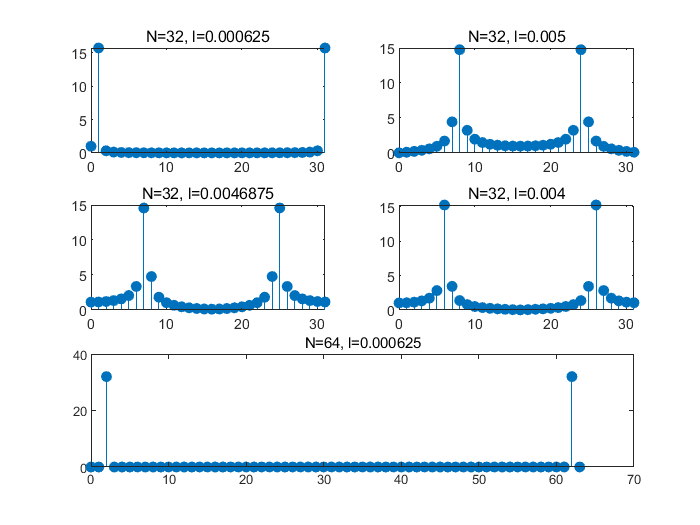

clc
clear
close all
%初始值
F = 50;
N = 32;
k = (0:(N-1));
%4种步长
l = [0.000625 0.005 0.0046875 0.004];
test = l.*(N-1);

%绘制前4个
for i = 1:4
    t = linspace(0,test(i),N+1);
    %t = (0:l(i):test(i));
    %x为离散时间序列
    x = cos(2 * pi * F .* t);
    y = fft(x,N);
    subplot(3,2,i);
    stem(k,abs(y),'filled');
    title(['N=32, l=',num2str(l(i))]);        
end

%绘制第5个
N2 = 64;
k2 = (0:(N2-1));
t2 = (0:l(1):l(1)*N2);
%x为离散时间序列
x = cos(2 * pi * F .* t2);
y = fft(x,N2);
subplot(3,1,3);
stem(k2,abs(y),'filled');
title(['N=64, l=',num2str(l(1))]);